# Admittance Scan Test Harness

Admittance scanning is a data driven method of stability assessment, which uses only measurements you make at the point of interconnection (POI) of the resource to the grid.

You can use this test harness to obtain the frequency vs admittance characteristics of any three-phase element, like an RLC network, an three-phase inverter, load, renewable resources with inverters, etc.

## Test Harness Setup

This test harness provides an Admittance Scan block connected to an ideal grid. You connect the resource under test to the Admittance Scan block. The grid is operates at a frequency of 60 Hz and voltage of 4.16 kV. You can choose to operate the grid at any frequency and voltage level.

The Admittance Scan block measures the perturbations in currents by injecting series voltage perturbations at the POI. This source injects perturbation voltages, $\Delta v$, and the corresponding current perturbations, $\Delta i$, you measure. You use these perturbed voltages and currents to obtain the admittance of the system at the POI.

This figure shows an inverter based resource (IBR) connected to the grid for admittance scanning. The IBR admittance is represented using $Y_A$.

                              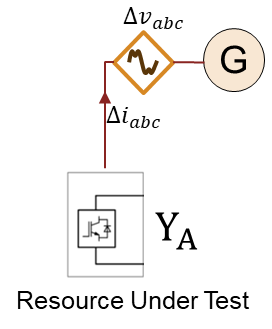                         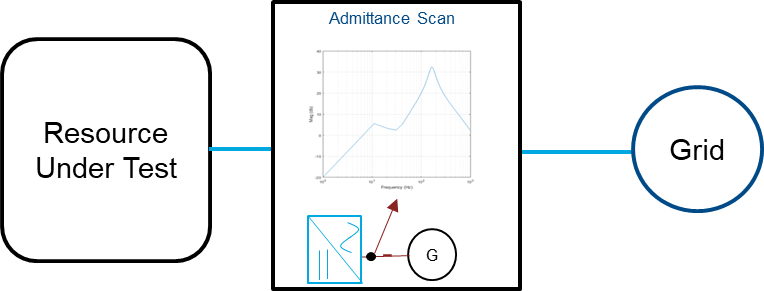

This work uses measurement and estimation of admittance in the Park transformed DQ reference frame. This system of equations describes the relationship between the admittance, perturbed voltages, $\Delta V$, and currents, $\Delta i$, along the D and Q axis.

$\left\lbrack \begin{array}{cc}
Y_{\textrm{DD}}  & Y_{\textrm{DQ}} \\
Y_{\textrm{QD}}  & Y_{\textrm{QQ}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta V}_D \\
{\Delta V}_Q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
{\Delta i}_D \\
{\Delta i}_Q 
\end{array}\right\rbrack$, here $Y$ represents the admittance of the resource.

The Admittance Scan block is a custom component that injects voltage disturbances in the form of a pseudo random binary sequence (PRBS). The amplitude of the PRBS signal can be selected through the mask, the perturbations can be injected sequentially on the D axis / Q axis.

The  `admittancescanPRBS.m `performs the admittance scan on the simulated data and estimates the admittance transfer function of the resource. For more information about the Admittance Scan block, see the  `AdmittanceScanofIBRsDescription `script`.`

## Configure Model to Run and Obtain Admittance Scan Plots

In this section, you perform an admittance scan and verify the results. You test two resources: 

a star connected three-phase RLC load and a simplified grid-following (GFL) source.

### Star Connected Three-Phase RLC Load

A star connected three-phase RLC load is considered as the resource under test and the admittance scan is performed in the DQ domain. 

Plot the admittance scan in the DQ domain for the star-connection three-phase RLC load.

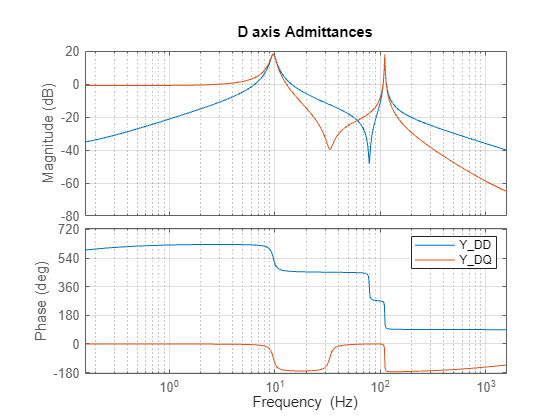

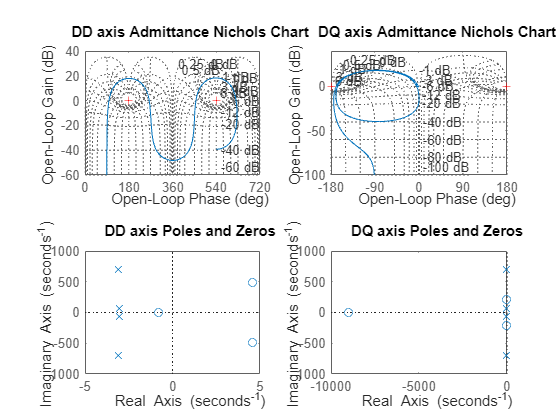

model='TestHarness'; % Test model 
open_system(model); % Loading the model
set_param('TestHarness/Resource Under Test','Choice','Y Connected Load'); % Configure test model with Star connect RLC load
scan.Vd=0.02; % Magnitude of disturbance along D- axis (PU)
scan.Vq=0.0;  % Magnitude of disturbance along Q- axis (PU)
scan.f=[1:1e4]/(2*pi); % Range of disturbance frequency in Hz
Data=sim(model);% Simulate model
modelorder=4; % Choose order of the estimated model 
Y1D=admittancescanPRBS(scan.Vd,scan.Vq,scan.f,Data,modelorder); 

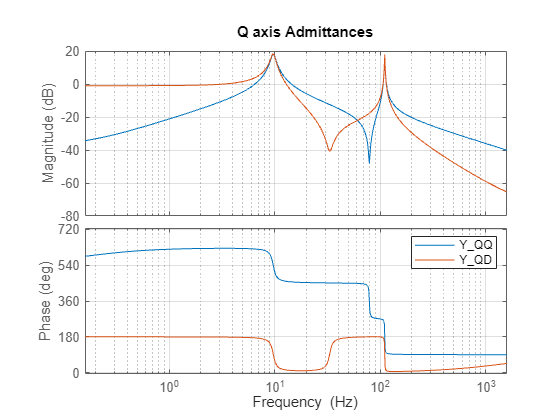

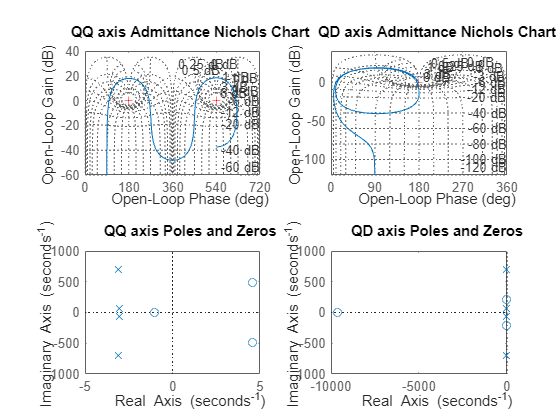

scan.Vd=0; % Magnitude of disturbance along D- axis (PU)
scan.Vq=0.02; % Magnitude of disturbance along Q- axis (PU)
Data=sim(model);% Simulate model
modelorder=4; % Choose order of the estimated model 
Y1Q=admittancescanPRBS(scan.Vd,scan.Vq,scan.f,Data,modelorder); 

#### Analyze Scan Results Theoretically

This equation defines the admittance transfer function of the series RLC load connected to the ideal grid.

$Y_{RLC}=\frac{I(s)}{V(s)}=\frac{-\frac{s}{L}}{s^2+\frac{R}{L}s+\frac{1}{LC}}$ , Where R, L, and C are the resistance, inductance, and capacitance, respectively, of the load, and s is the Laplace operator. 

tFLoad=tf(-1*[1/loadl.l 0],[1 loadl.r/loadl.l 1/(loadl.l*loadl.c)]) % Calculate the transfer function using the tf function.

tFLoad =
 
      -100 s
  --------------
  s^2 + s + 1e05
 
Continuous-time transfer function.
Model Properties


 A general DQ voltage/ current at a frequency, $\omega_{dq}$, is equivalent to two sequence-domain voltage phasors at different frequencies, shifted by the fundamental frequency, $\omega_{0}$: 

-   One in the positive sequence voltage at: $\omega_{p}=\omega_{dq}+\omega_{0}$ ;

-   Another in the negative sequence voltage at :$\omega_{n}=\omega_{dq}-\omega_{0}$. 

The transfer function, $Y_{RLC}$, is in the abc domain. You can obtain the equivalent admittance in the DQ domain using this transformation.

                                                                                                          $Y_{DQ}=A^{-1}Y_{pn}A$, where $A=\left\lbrack \begin{array}{cc}
1 & 1\\
-1j & 1j
\end{array}\right\rbrack$, is the transformation matrix.

Compare the analytical and estimated transfer functions.

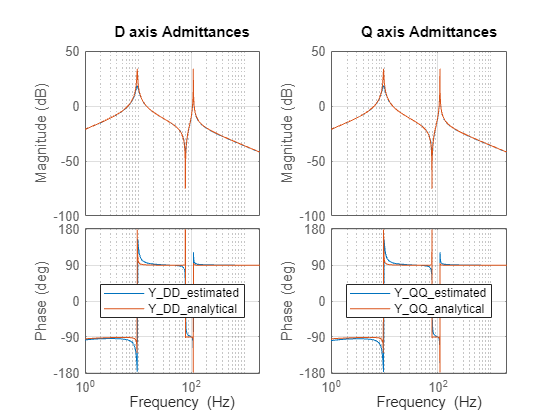

s=tf('s');
Yp=-(100*(s+j*2*pi*60)/((s+j*2*pi*60)^2+(s+j*2*pi*60)+1e5)); % Positive sequence admittance
Yn=-(100*(s-j*2*pi*60)/((s-j*2*pi*60)^2+(s-j*2*pi*60)+1e5)); % Negative sequence admittance
A=[1 1;-1j 1j]; % Positive negative sequence to DQ axis admittance transformation
YDQ=A^-1*[Yp 0;0 Yn]*A; % DQ axis admittance
figure; %Plotting the Bode plots for the admittance
subplot(1,2,1) %D axis admittance
hp11=bodeplot(Y1D(1),YDQ(1,1),{2*pi,2000*(2*pi)}); % Bode plot of estimated vs analytical admittance
setoptions(hp11,'FreqUnits','Hz','grid','on','PhaseWrapping','on','PhaseWrappingBranch',-180);
legend('Y_DD_estimated','Y_DD_analytical','Location','best');
title('D axis Admittances');
subplot(1,2,2) % Q axis admittance
hp11=bodeplot(Y1Q(1),YDQ(2,2),{2*pi,2000*(2*pi)}); % Bode plot of estimated vs analytical admittance
setoptions(hp11,'FreqUnits','Hz','grid','on','PhaseWrapping','on','PhaseWrappingBranch',-180);
legend('Y_QQ_estimated','Y_QQ_analytical','Location','best');
title('Q axis Admittances');

The bode plot for the estimated admittance transfer function is very close to that of the analytical transfer function of the RLC load.

### Simplified Grid-Following (GFL) Source

In this section, you model a simplified grid-following (GFL) current source as the device under test. You determine the output currents from the source using an admittance transfer function along the D-axis.

This figure shows the control architecture of the simplified GFL current source.

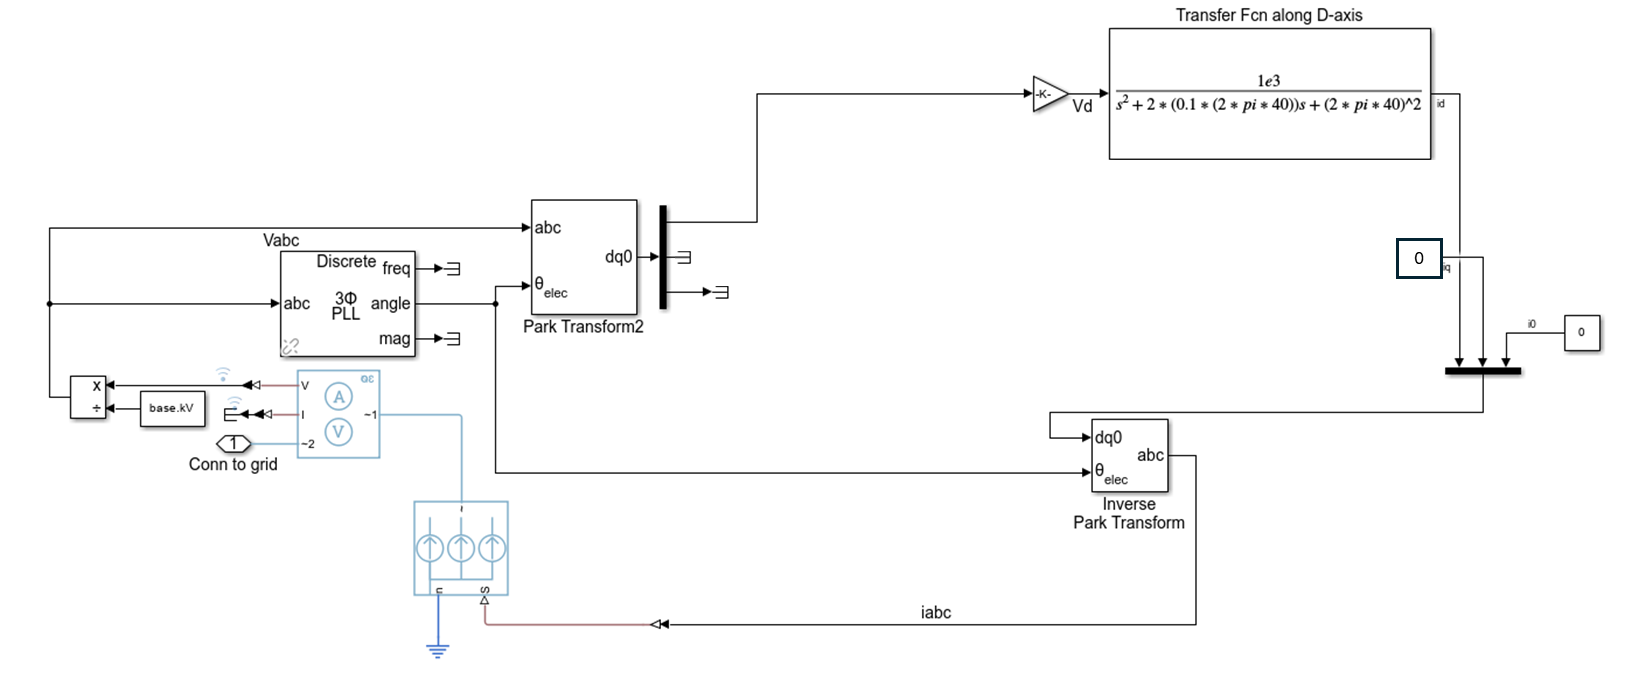

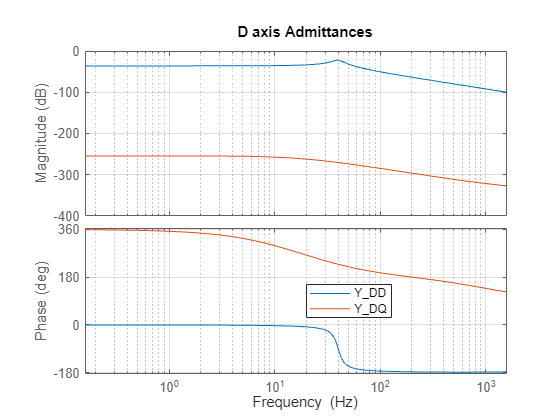

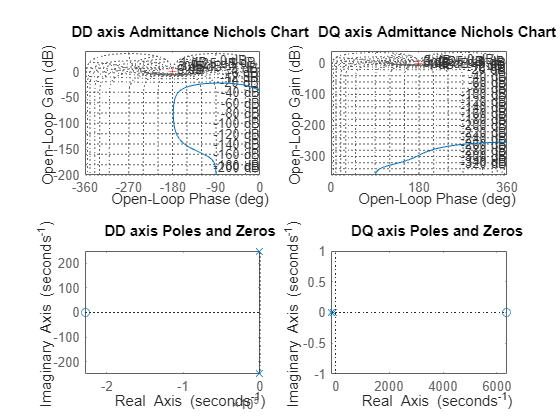

set_param('TestHarness/Resource Under Test','Choice','Simplified GFL Source'); % Configure test model with Simplified GFL source
scan.Vd=0.01; % Magnitude of disturbance along D- axis (PU)
scan.Vq=0.0; % Magnitude of disturbance along Q- axis (PU)
Data=sim(model);% Simulate model
modelorder=2; % Choose order of the estimated model 
Y2D=admittancescanPRBS(scan.Vd,scan.Vq,scan.f,Data,modelorder); 

#### Analyze Scan Results Theoretically

You can model the GFL current source using an admittance transfer function of your choice. 

This transfer function takes the voltages along the D' and Q' axes as inputs. This equation defines the analytical transfer function along the D axis.


$${Y_{DD}}=\frac{10^3}{s^2+2*0.1*(2*pi*40)+(2*pi*40)^2}$$
                                                                       

s=tf('s');
V1=mean((Data.get('Vd').Data((scan.start)*scan.samplingfrequency)));  % Measurement before injecting disturbance
I1=-mean((Data.get('id').Data((scan.start)*scan.samplingfrequency))); % Measurement before injecting disturbance
Hpll=(pll.kp/base.kV+(pll.ki/base.kV)*1/s); % PLL transfer function along Q-axis
Gpll=(Hpll/s/(1+(V1)*Hpll/s)); % Closed loop transfer function of PLL
YDDpll=tf(1e3,[1 2*0.1*(2*pi*40) (2*pi*40)^2]); % Transfer function of simplified admittance block
YDD=YDDpll; % D axis admittance in grid reference frame

Compare the analytical and estimated transfer functions.

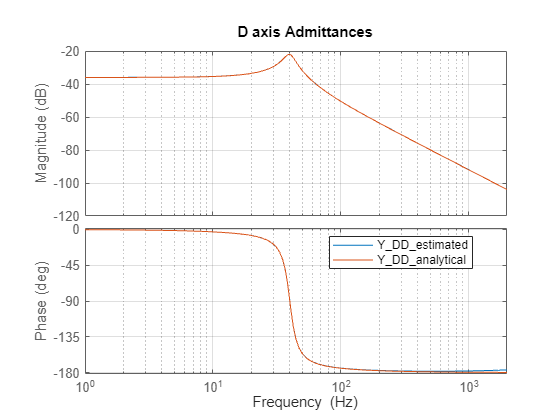

figure;%Plotting the Bode plots for the D axis admittance
hp12=bodeplot(Y2D(1),YDD,{2*pi,2000*(2*pi)}); % Bode plot of estimated vs analytical admittance
setoptions(hp12,'FreqUnits','Hz','grid','on','PhaseWrapping','on','PhaseWrappingBranch',-180);
legend('Y_DD_estimated','Y_DD_analytical','Location','best');
title('D axis Admittances');

### Grid Following Inverter with Current Control 

Grid following (GFL) inverters are designed to synchronize with the grid using a phase locked loop (PLL), and inject power into the electrical grid.

This figure shows the overall control and functioning of a grid connected GFL inverter.

               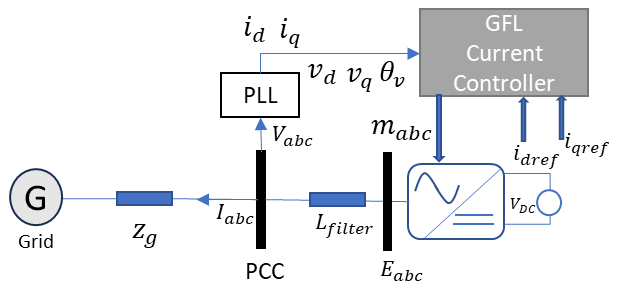

Here,

-    $V_{abc}$ represents the gird voltage at the POI.

-     $I_{abc}$ represents the injected current at the POI.

-     $\theta$ represents the phase of the grid voltage at the POI.

-     $i_{dref}, i_{qref}$  represents the reference currents.

-     $L_{filter}$  represents the filter inductance of the inverter.

-     $E_{abc}$ represents the internal voltage of the inverter.

This equations represents the relationship between the voltages and currents at he POI.

                                                                             
$$\frac{d}{\textrm{dt}}\left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0 & \omega L_{\textrm{filter}} \\
-\omega L_{\textrm{filter}}  & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \\
i_q 
\end{array}\right\rbrack +\left\lbrack \begin{array}{c}
E_d \\
E_q 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
V_d \\
V_q 
\end{array}\right\rbrack$$


At sinusoidal steady state this relationship can be defined as:

                                                                           
$$\left\lbrack \begin{array}{cc}
sL_{\textrm{filter}}  & \omega L_{\textrm{filter}} \\
-\omega L_{\textrm{filter}}  & sL_{\textrm{filter}} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
i_d \left(s\right)\\
i_q \left(s\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
E_d \left(s\right)\\
E_q \left(s\right)
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
V_d \left(s\right)\\
V_q \left(s\right)
\end{array}\right\rbrack$$


Here, $s$ is the Laplace operator.

The PLL tracks the grid frequency and phase of the grid voltage at the POI, using a proportional-integral controller followed by a integrator along the Q axis voltage. 

This figure shows the control block diagram of the PLL.

                                                                                        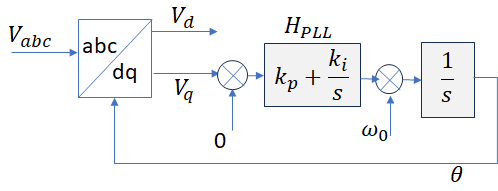

However, when you inject perturbation in POI voltages, the PLL frame will be displaced from the grid-voltage frame by an angle Δθ [1]. Three-phase variables in the grid-voltage frame (DQ), represented as $x_d ,x_q ,$ and the PLL frame (D'Q') during the perturbation, represented as ${x_d }^{\prime } ,{x^{\prime } }_q ,$ are related as:

                                                                                                                           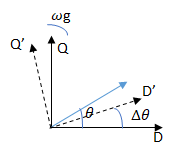

                                                                                                                           
$$\left\lbrack \begin{array}{c}
{{\Delta x}_d }^{\prime } \\
{{\Delta x}_q }^{\prime } 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & \Delta \theta \\
-\Delta \theta  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\Delta x}_d \\
\Delta x_q 
\end{array}\right\rbrack$$


This equation defines the linear response of the error angle to the perturbation in D- and Q-axis voltages.

                                                                 $\Delta \theta \left(s\right)=\frac{\frac{H_{\textrm{PLL}} \left(s\right)}{s}}{1+V_1 \frac{H_{\textrm{PLL}} \left(s\right)}{s}}\Delta V_q \left(s\right)$,   where $H_{\textrm{PLL}} \left(s\right)$ is the PI controller transfer function of the PLL.

These equations define the voltages and currents, when you inject perturbations in the D- and Q-axis voltage, $\Delta V_d ,\Delta V_q$ .

                                                                                                         
$$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;V_q \left(s\right)=0+\Delta V_q \left(s\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;V_d \left(s\right)=V_1 +\Delta V_d \left(s\right)\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;I}_d \left(s\right)=I_1 +\Delta i_d \left(s\right)\\
{\;\;\;\;\;\;\;\;\;\;\;\;\;I}_q \left(s\right)=0+\Delta i_q \left(s\right)\\
\\
\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\Delta \theta \left(s\right)=\frac{\frac{H_{\textrm{PLL}} \left(s\right)}{s}}{1+V_1 \frac{H_{\textrm{PLL}} \left(s\right)}{s}}\Delta V_q \left(s\right)=G_{\textrm{PLL}} \left(s\right)\Delta V_q \left(s\right)\\
\;\;\;\Rightarrow \Delta {i_d }^{\prime } =\Delta i_d \\
\;\;\;\Rightarrow \Delta {i_q }^{\prime } =\Delta i_q \left(s\right)-I_1 \Delta \theta \left(s\right)={\Delta i_q \left(s\right)-I_1 G}_{\textrm{PLL}} \left(s\right)\Delta V_q \left(s\right)\\
\;\Delta {V_q }^{\prime } =\Delta V_q \left(s\right)-V_1 \Delta \theta \left(s\right)={\Delta V_q \left(s\right)\left(1-{V_1 G}_{\textrm{PLL}} \left(s\right)\right)} 
\end{array}
\end{array}$$


The current control loop of a GFL inverter typically uses two PI controllers to track the reference currents along the D and Q axis. This figure shows the current Control loop of the GFL inverter. 

                                                                                 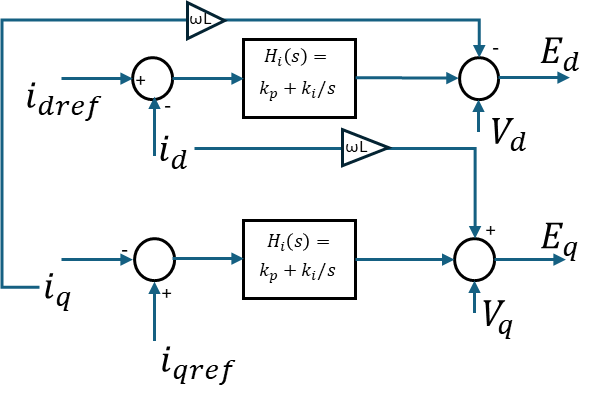

Using the above relationships between the bus voltages and currents and the current controller transfer-function, $H_i \left(s\right)$, the admittance of the GFL inverter at the POI can be derived as [1]:

                                                                                                                                      
$$Y_{DD}=\frac{I_d}{V_d}=\frac{1}{sL+V_{dc}H_{i}(s)$$


                                                                                                                                     
$$Y_{QQ}=\frac{I_q}{V_q}=\frac{-1+\frac{H_{pll}(s)*(V_d+I_dV_{dc}H_{i}(s))}{1+V_dH_{pll}(s)}}{sL+V_{dc}H_{i}(s)$$


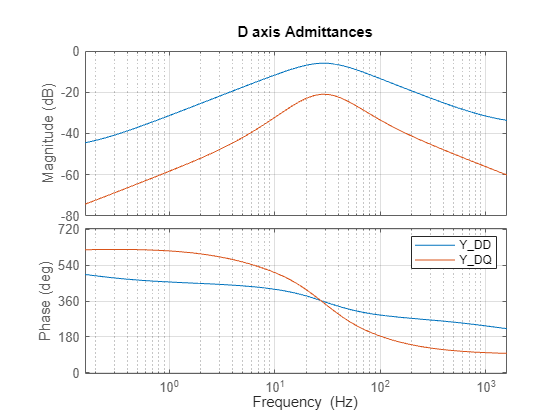

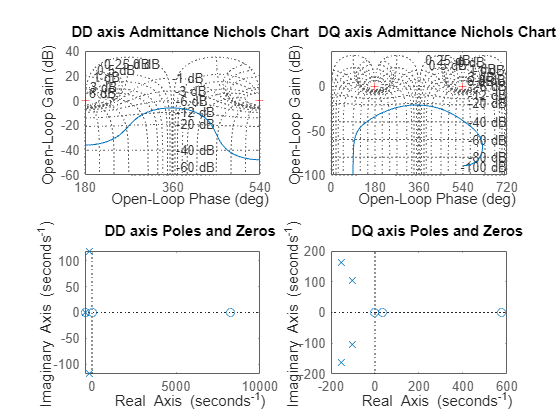

set_param('TestHarness/Resource Under Test','Choice','GFL BESS'); % Configure test model with Simplified GFL source
scan.Vd=0.04; % Magnitude of disturbance along D- axis (PU)
scan.Vq=0.0; % Magnitude of disturbance along Q- axis (PU)
Data=sim(model);% Simulate model
modelorder=4; % Choose order of the estimated model 
Y2D=admittancescanPRBS(scan.Vd,scan.Vq,scan.f,Data,modelorder);

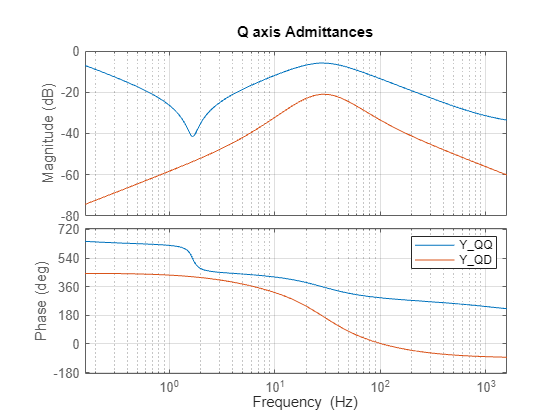

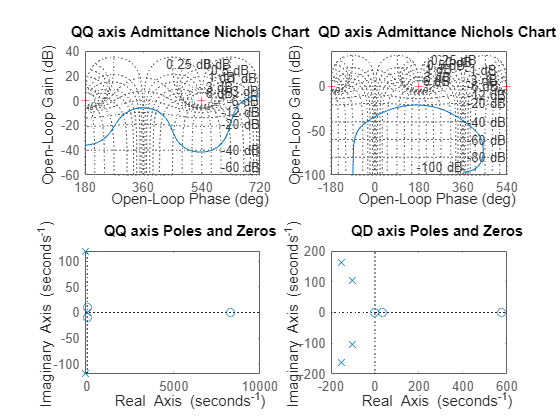

scan.Vd=0.0; % Magnitude of disturbance along D- axis (PU)
scan.Vq=0.04; % Magnitude of disturbance along Q- axis (PU)
Data=sim(model);% Simulate model
modelorder=4; % Choose order of the estimated model 
Y2Q=admittancescanPRBS(scan.Vd,scan.Vq,scan.f,Data,modelorder);

#### Validation of Estimated Results with Analytical Admittance

s=tf('s');
V1=mean((Data.get('Vd').Data((scan.start-0.1)*scan.samplingfrequency)));  % Measurement before injecting disturbance
I1=mean((Data.get('id').Data((scan.start-0.1)*scan.samplingfrequency))); % Measurement before injecting disturbance
Hpll=(0.01+(2.05)*1/s)/base.kV; % PLL transfer function along Q-axis
Gpll=Hpll/s/(1+V1*Hpll/s); % Closed loop transfer function of PLL
Hi=(PVController.Kp_ic+PVController.Ki_ic/s); % Controller transfer function
YDD=(1)/(s*10*PVInverter.L/base.z+Hi); % D axis admittance in grid reference frame
YQQ=(1-(Hpll*(V1+I1*Hi)/(1+V1*Hpll)))/(s*10*PVInverter.L/base.z+Hi);% Q axis admittance in grid reference frame

Compare the analytical and estimated transfer functions.

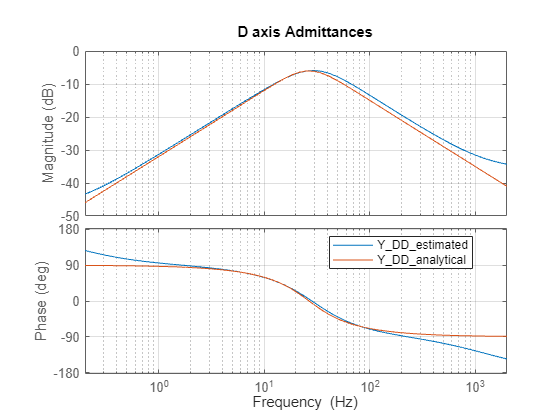

figure;%Plotting the Bode plots for the D axis admittance
hp12=bodeplot(Y2D(1),YDD,{2*pi*0.2,2000*(2*pi)}); % Bode plot of estimated vs analytical admittance
setoptions(hp12,'FreqUnits','Hz','grid','on','PhaseWrapping','on','PhaseWrappingBranch',-180);
legend('Y_DD_estimated','Y_DD_analytical','Location','best');
title('D axis Admittances');

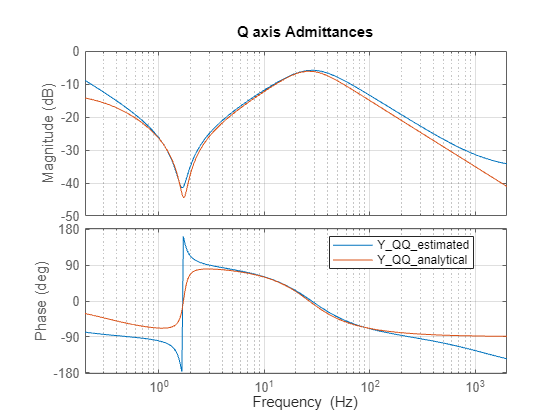

figure;%Plotting the Bode plots for the D axis admittance
hp12=bodeplot(Y2Q(1),YQQ,{2*pi*0.2,2000*(2*pi)}); % Bode plot of estimated vs analytical admittance
setoptions(hp12,'FreqUnits','Hz','grid','on','PhaseWrapping','on','PhaseWrappingBranch',-180);
legend('Y_QQ_estimated','Y_QQ_analytical','Location','best');
title('Q axis Admittances');

### Summary

This is a test harness where you can use the Admittance Scan block to inject PRBS voltage disturbance to obtain voltage and current measurements at different frequencies. After obtaining the perturbed measurements, you can use the `admittancescanPRBS(Vd,Vq,f,data,modelorder) `function to obtain the admittance spectrum of the resource that you are testing. Once the test results are obtained you can verify them analytically using this script.

**Reference**

- S. Shah and L. Parsa, "Impedance Modeling of Three-Phase Voltage Source Converters in DQ, Sequence, and Phasor Domains," in *IEEE Transactions on Energy Conversion*, vol. 32, no. 3, pp. 1139-1150, Sept. 2017